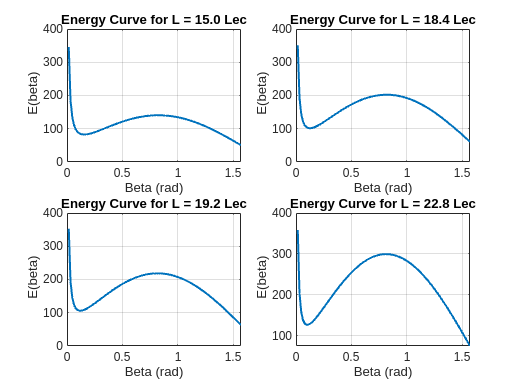

% Parameters
L_values = [15, 18.4, 19.2, 22.8]; % Values of L in multiples of Lec
Lec = 0.55; % Elasto-capillary length in mm
D_star = 2.93 * Lec; % Extent of wet region
V = 92.4 * Lec^3; % Volume of drop
EI = 1; % Non-dimensional bending rigidity
rho_g_w_h = 1; % Normalized weight per unit length
gamma = 1; % Surface tension coefficient
theta_Y = deg2rad(110); % Static contact angle in radians
theta_advance = deg2rad(150); % Advancing contact angle in radians

% Discretize beta
beta = linspace(0, pi/2, 100); % Beta from 0 to pi/2

% Create a single figure with subplots
figure;

for i = 1:length(L_values)
    L = L_values(i);
    
    % Compute non-dimensional energy curve
    E_tilde = arrayfun(@(b) total_energy(b, D_star, L, Lec, EI, ...
        rho_g_w_h, gamma, theta_Y, theta_advance, V), beta);
    
    % Select subplot position
    subplot(2, 2, i);
    plot(beta, E_tilde, 'LineWidth', 1.5);
    
    % Labels and title
    xlabel('Beta (rad)');
    ylabel(' E(beta)');
    title(sprintf('Energy Curve for L = %.1f Lec', L));
    grid on;
end


% Total energy function
function E = total_energy(beta, D_star, L, Lec, EI, rho_g_w_h, ...
                          gamma, theta_Y, theta_advance, V)
    % Constraints
    k = beta / D_star; % Curvature
    if beta < theta_advance
        D = D_star;
    else
        D = beta / k; % Wet region extent
    end
    
    % Elastic energy
    E_el = EI * k^2 * D;

    % Gravitational energy
    term1 = (2 * D - sin(2 * k * D)) / k;
    term2 = (1 - cos(2 * k * D)) * (L - D) / k;
    term3 = 0.5 * (L - D)^2 * sin(2 * k * D);
    E_g = rho_g_w_h * (term1 + term2 + term3);

    % Surface energy
    surface_arc = gamma * (2 * D); % Simplified arc length term
    surface_solid_liquid = gamma * D; % Solid-liquid contribution
    surface_solid_air = gamma * (L - D); % Solid-air contribution
    E_s = surface_arc + surface_solid_liquid + surface_solid_air;
    
    % Total energy
    E = E_el + E_g + E_s;
end
